# Data Averaging

 Ramsey

## Data Input 

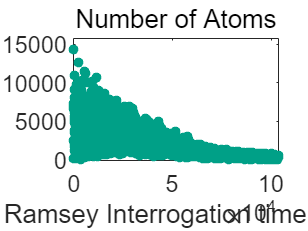

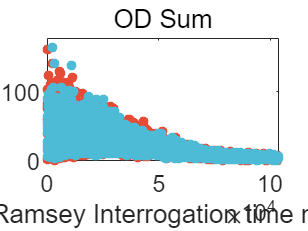

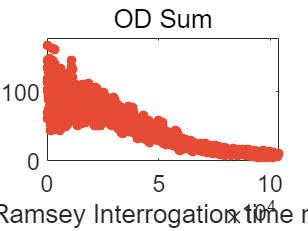

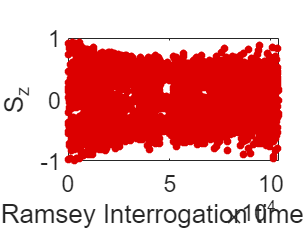

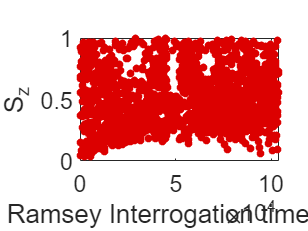

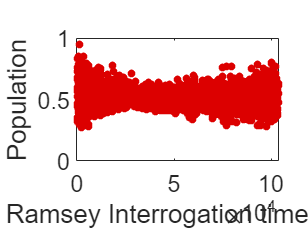

close all
clear all 
colors=npg(100); %  basic colors
main_dir='\\Artemis-pc\e\Data\2022-12-10\Abs-4329';
save_dir='D:\Documents\MATLAB\Figures for Yb-173\CssData';

load([main_dir,'\result.mat']);

clear relativeOD_fit coeff coeffoutput coefferr main_dir

## Reshape data


x_label='Ramsey interrogation time s';
x_lim_low=0;
x_lim_high=1.050;
y_lim_low=-1.0;
y_lim_high=1.0;

precess_1_list=((0:30:1050)+6)/1000; % s

% sampling rate 33 Hz
% 5f 12 Hz
precess_1_list_plot=(-200:5:1250)/1000; % 5 ms
timestep=0.005;

precess_2_list=[0,1.1:1.1:4.4,8,12,20:20:180];% s

length_0=length(relativeOD);
length_1=length(precess_1_list);
length_2=length(precess_2_list);

% reshape in row

% matrix_1 (N+ - N-)/(N+ + N-)
% matrix_2 (N+ + N-)
% matrix_3 (N+ + N-)/ N
% matrix_4  N+ / N
% matrix_5  N+ / N

matrix_1=reshape(relativeOD,length_1,length_0/length_1/length_2,length_2);
matrix_2=reshape(ODsum1+ODsum2,length_1,length_0/length_1/length_2,length_2);
matrix_3=reshape((ODsum1+ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);
matrix_4=reshape((ODsum1)./ODsum3,length_1,length_0/length_1/length_2,length_2);
matrix_5=reshape((ODsum2)./ODsum3,length_1,length_0/length_1/length_2,length_2);

% clear first data run
matrix_1(:,1,:)=[];
matrix_2(:,1,:)=[];
matrix_3(:,1,:)=[];
matrix_4(:,1,:)=[];
matrix_5(:,1,:)=[];

%
mean_1=mean(matrix_1,2); % mean in dim 2
std_1=std(matrix_1,0,2); % weight 0, dim 2
weight_1=1./std_1.^2;

mean_2=mean(mean(matrix_2,2),1);
std_2=mean(std(matrix_2,0,2),1);
weight_2=1./std_2.^2;

mean_3=mean(matrix_3,2);
std_3=std(matrix_3,0,2);
weight_3=1./std_3.^2;

mean_4=mean(matrix_4,2);
std_4=std(matrix_4,0,2);
weight_4=1./std_4.^2;

mean_5=mean(matrix_5,2);
std_5=std(matrix_5,0,2);
weight_5=1./std_5.^2;

%  use data in form of (:,:,i)


## Sindusal fitting two state

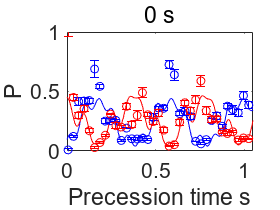

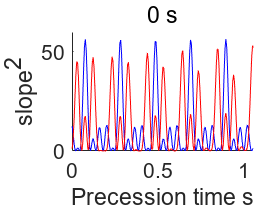

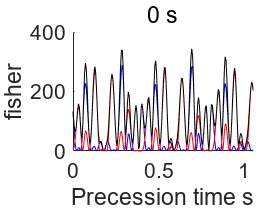

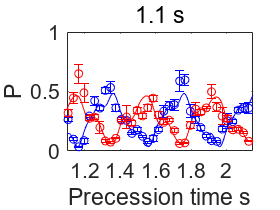

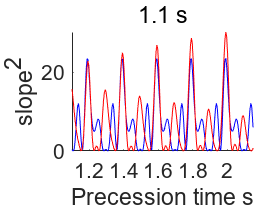

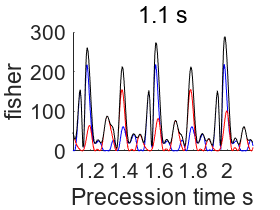

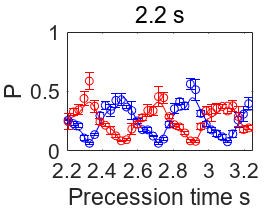

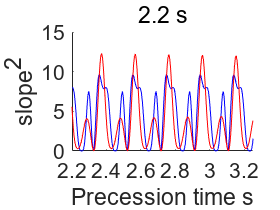

betaraw=[
    0.4815    0.5166    0.7436    0.6235    2.4515    2.5183   -2.6478   -2.7758    0.1101    0.2819    1.4827   -1.9174    0.1967    0.1732   -1.2999    2.0128
    0.5198    0.5249    0.6916    0.6002    2.4964    2.5871    2.5833    2.3152    0.1566    0.2161   -0.2011    0.9522    0.0838    0.0547   -1.6104   -3.0693
    0.5217    0.4875    0.5985    0.5803    2.5640    2.5577    1.3829    1.3525    0.1227    0.1322    2.8095    3.0556    0.0396    0.0095   -0.1745   -3.0864
    0.5749    0.5402    0.6784    0.6693    2.5840    2.5847    0.4158    0.3315    0.1441    0.1225   -0.6285   -0.9118    0.0203    0.0361   -2.0722   -0.2650
    0.5435    0.5284    0.6383    0.6094    2.5643    2.5774   -0.4695   -0.5553    0.1386    0.1405    2.5335    2.5269    0.0013    0.0161   -1.0960    0.1675
    0.5368    0.4919    0.6039    0.5190    2.5605    2.6071    1.5594    1.3948    0.1466    0.1508    0.6233    0.8532    0.0239    0.0365    2.3341    0.3778
    0.5382    0.4828    0.5943    0.5104    2.5818    2.6072   -2.5264   -2.5721    0.1479    0.1606   -0.9340   -0.6086    0.0137    0.0154   -1.8080   -2.7663
    0.5323    0.4823    0.5886    0.4820    2.5752    2.5841    2.0479    2.0105    0.1463    0.1917    3.0033    3.1206    0.0133    0.0042   -3.1092    2.3891
    0.5255    0.4860    0.5474    0.4609    2.5519    2.5829    0.9620    0.8818    0.1420    0.1705   -2.9537   -2.8074    0.0097    0.0126   -1.4885    0.3355
    0.5194    0.5247    0.5411    0.4783    2.5786    2.6172   -0.3649   -0.4367    0.1421    0.1491    3.1218    3.1260    0.0195    0.0477    0.1653   -1.7088
    0.5258    0.5009    0.5418    0.5159    2.6077    2.6105   -1.7305   -1.8158    0.1398    0.1168   -3.0759   -3.1804    0.0074    0.0243    0.1297    2.8904
    0.5182    0.4784    0.5227    0.3726    2.5907    2.5963   -2.5987   -2.6608    0.1553    0.1469   -2.9747   -2.5855   -0.0111    0.0362    1.3680    1.5862
    0.5192    0.4860    0.4824    0.4062    2.6383    2.6172    2.3553    2.5968    0.1328    0.1252   -3.0599   -2.8097    0.0516    0.0214   -2.9852   -1.0770
    0.5158    0.5057    0.4868    0.4290    2.6024    2.6152    0.9363    0.9443    0.1052    0.1486   -2.0580   -2.5073    0.0462    0.0244    0.8904   -2.8218
    0.5190    0.4997    0.4626    0.3965    2.5715    2.6350    0.0690   -0.1423    0.1262    0.1473   -1.5923   -1.9034    0.0263    0.0190    1.5870    2.8305
    0.5238    0.5353    0.5255    0.4498    2.5476    2.5675   -1.2547   -1.2103    0.0972    0.1632   -0.9962   -1.7158    0.0553    0.0617    3.1138   -1.1653
    ];
% p+ p- c+1 c-1 f+ f- phi+1 phi-1  c+3 c-3 phi+3 phi-3 c+5 c-5  phi+5 phi-5
beta_list=zeros(size(mean_1,3),16);
beta_err_list=zeros(size(mean_1,3),16);

for i = 1:size(mean_1,3)
    %for i=1:1
    x_cell={precess_1_list,precess_1_list};
    y_cell={transpose(mean_4(:,:,i)),transpose(mean_5(:,:,i))};
    w_cell={transpose(weight_4(:,:,i)),transpose(weight_5(:,:,i))};
    % beta fitting parameters
    mdl1 = @(beta,x) beta(1)/2*(1+beta(3)*cos(2*pi*beta(5)*x+beta(7))+beta(9)*cos(2*pi*3*beta(5)*x+beta(11))+beta(13)*cos(2*pi*5*beta(5)*x+beta(15)));
    mdl2 = @(beta,x) beta(2)/2*(1-beta(4)*cos(2*pi*beta(6)*x+beta(8))-beta(10)*cos(2*pi*3*beta(5)*x+beta(12))-beta(14)*cos(2*pi*5*beta(5)*x+beta(16)));

    mdl_cell = {mdl1, mdl2};
    beta0=betaraw(i,:);
    [beta,r,J,Sigma,mse,errorparam,robustw] = nlinmultifit(x_cell, y_cell, mdl_cell, beta0,'weights',w_cell);
    % Calculate model predictions and confidence intervals
    [ypred1,delta1] = nlpredci(mdl1,precess_1_list_plot,beta,r,'covar',Sigma);
    [ypred2,delta2] = nlpredci(mdl2,precess_1_list_plot,beta,r,'covar',Sigma);
    beta_list(i,:)=beta;
    % Calculate parameter confidence intervals
    ci = nlparci(beta,r,'Jacobian',J);
    beta_err_list(i,:)=ci((length(ci)+1):(2*length(ci)))-ci(1:length(ci));

    fig_p2=figure;
    hold all;
    box on;

    plot(precess_1_list_plot+precess_2_list(i),ypred1,'Color','blue');
    plot(precess_1_list_plot+precess_2_list(i),ypred2,'Color','red');

    errorbar(precess_1_list+precess_2_list(i),mean_4(:,:,i),std_4(:,:,i),'o','Color','blue');
    errorbar(precess_1_list+precess_2_list(i),mean_5(:,:,i),std_5(:,:,i),'o','Color','red');

    title([num2str(precess_2_list(i)),' s']);
    ylim([0 1]);
    ylabel('P');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)]);
    ylim([0 y_lim_high]);
    saveas(fig_p2,[save_dir,'\Figure_p2_',num2str(i),'.png'])
    savefig(fig_p2,[save_dir,'\Figure_p2_',num2str(i),'.fig'])


    % need a loss factor
    diff_y1=diff(ypred1)./timestep;
    diff_y2=diff(ypred2)./timestep;

    fig_diff_y=figure;
    hold on
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y1.^2,'Color','blue');
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y2.^2,'Color','red');


    title([num2str(precess_2_list(i)),' s']);
    %ylim([-10 10]);
    ylabel('slope^2');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)]);


    fig_fisher_y=figure;
    hold on
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y1.^2./(ypred1(1:end-1)+ypred1(2:end))*2,'Color','blue');
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y2.^2./(ypred2(1:end-1)+ypred2(2:end))*2,'Color','red');
    plot(precess_1_list_plot(2:end)-timestep/2+precess_2_list(i),diff_y1.^2./(ypred1(1:end-1)+ypred1(2:end))*2+diff_y2.^2./(ypred2(1:end-1)+ypred2(2:end))*2,'Color','black');

    fisher(i)=max(diff_y1.^2./(ypred1(1:end-1)+ypred1(2:end))*2+diff_y2.^2./(ypred2(1:end-1)+ypred2(2:end))*2);
    title([num2str(precess_2_list(i)),' s']);
    %ylim([-10 10]);
    ylabel('fisher');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)]);
end

% p+ p- c+1 c-1 f+ f- phi+1 phi-1  c+3 c-3 phi+3 phi-3 c+5 c-5  phi+5 phi-5
p_1=beta_list(:,1);
p_2=beta_list(:,2);
contrast_1=beta_list(:,3);
contrast_2=beta_list(:,4);
freq_1=beta_list(:,5);
freq_2=beta_list(:,6);
phase_1=beta_list(:,7);
phase_2=beta_list(:,8);
contrast_3=beta_list(:,9);
contrast_4=beta_list(:,10);
phase_3=beta_list(:,11);
phase_4=beta_list(:,12);
contrast_5=beta_list(:,13);
contrast_6=beta_list(:,14);
phase_5=beta_list(:,15);
phase_6=beta_list(:,16);


p_1_err=beta_err_list(:,1);
p_2_err=beta_err_list(:,2);
contrast_1_err=beta_err_list(:,3);
contrast_2_err=beta_err_list(:,4);
freq_1_err=beta_err_list(:,5);
freq_2_err=beta_err_list(:,6);
phase_1_err=beta_err_list(:,7);
phase_2_err=beta_err_list(:,8);
contrast_3_err=beta_err_list(:,9);
contrast_4_err=beta_err_list(:,10);
phase_3_err=beta_err_list(:,11);
phase_4_err=beta_err_list(:,12);
contrast_5_err=beta_err_list(:,13);
contrast_6_err=beta_err_list(:,14);
phase_5_err=beta_err_list(:,15);
phase_6_err=beta_err_list(:,16);


## Plot population decay - two parts

f_population_decay_2=figure;
hold all
h1=errorbar(precess_2_list',p_1,p_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',p_2,p_2_err,'o','Color','red');

eqn='a*exp(-x^1/b^1)+c';
startpoints=[0.5 1 1];
lower=[0 0 0];
upper=[1.1 2000000 1];


fi_pop_coherent=fit(precess_2_list',p_1,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_1_err.^2);
fi_pop_coherent_p1=fi_pop_coherent

fi_pop_coherent_p1 =      常规模型:
     fi_pop_coherent_p1(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =   5.827e-08
       b =     0.00954
       c =      0.5297  (0.5228, 0.5365)

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');

fi_pop_coherent=fit(precess_2_list',p_2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_2_err.^2);
fi_pop_coherent_p2=fi_pop_coherent

fi_pop_coherent_p2 =      常规模型:
     fi_pop_coherent_p2(x) = a*exp(-x^1/b^1)+c
     系数(置信边界为 95%):
       a =     0.06426  (-0.06116, 0.1897)
       b =        3.31  (-3.188, 9.808)
       c =      0.4925  (0.4799, 0.5051)

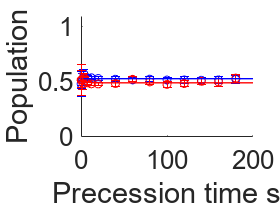

plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');

ylabel('Population');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1.1])
set(gca,'YScale','linear')

f_population_diff_decay_2=figure;

h1=errorbar(precess_2_list',p_1-p_2,sqrt(p_1_err.^2+p_2_err.^2),'o','Color','blue');

ylabel('Population difference');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.1 0.1])
set(gca,'YScale','linear')

saveas(f_population_decay_2,[save_dir,'\Figure_p_decay.png'])

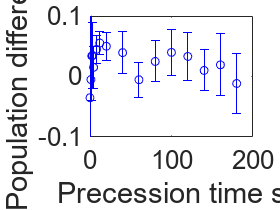

savefig(f_population_decay_2,[save_dir,'\Figure_p_decay.fig'])

saveas(f_population_diff_decay_2,[save_dir,'\Figure_p_diff.png'])

savefig(f_population_diff_decay_2,[save_dir,'\Figure_p_diff.fig'])


## Plot contrast decay - two parts

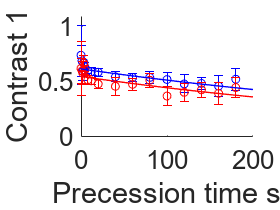

% c1 decay

f_contrast_decay_1=figure;
hold all
h1=errorbar(precess_2_list',contrast_1,contrast_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',contrast_2,contrast_2_err,'o','Color','red');

eqn='a*exp(-x^1/b^1)';
startpoints=[0.5 1];
lower=[0 0];
upper=[1.1 2000000];


fi_pop_coherent=fit(precess_2_list',contrast_1,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_1_err.^2);
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');

fi_pop_coherent=fit(precess_2_list',contrast_2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_2_err.^2);
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');

ylabel('Contrast 1');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1.1])
set(gca,'YScale','linear')

% c3 decay

f_contrast_decay_3=figure;
hold all
h1=errorbar(precess_2_list',contrast_3,contrast_3_err,'o','Color','blue');
h2=errorbar(precess_2_list',contrast_4,contrast_4_err,'o','Color','red');

eqn='a*exp(-x^1/b^1)';
startpoints=[0.5 1];
lower=[0 0];
upper=[1.1 2000000];


fi_pop_coherent=fit(precess_2_list',contrast_3,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_3_err.^2);
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');

fi_pop_coherent=fit(precess_2_list',contrast_4,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_4_err.^2);
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');

ylabel('Contrast 3');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1.1])
set(gca,'YScale','linear')

% c1 decay

f_contrast_decay_5=figure;
hold all
h1=errorbar(precess_2_list',contrast_5,contrast_5_err,'o','Color','blue');
h2=errorbar(precess_2_list',contrast_6,contrast_6_err,'o','Color','red');

eqn='a*exp(-x^1/b^1)';
startpoints=[0.5 1];
lower=[0 0];
upper=[1.1 2000000];


fi_pop_coherent=fit(precess_2_list',contrast_5,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_5_err.^2);
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');

fi_pop_coherent=fit(precess_2_list',contrast_6,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_6_err.^2);
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');

ylabel('Contrast 5');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1.1])
set(gca,'YScale','linear')

f_contrast_diff_decay_2=figure;

h1=errorbar(precess_2_list',contrast_1-contrast_2,sqrt(contrast_1_err.^2+contrast_2_err.^2),'o','Color','blue');

ylabel('Contrast difference');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.1 0.1])
set(gca,'YScale','linear')


saveas(f_contrast_decay_1,[save_dir,'\Figure_c1_decay.png'])

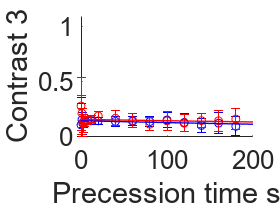

savefig(f_contrast_decay_1,[save_dir,'\Figure_c1_decay.fig'])

saveas(f_contrast_decay_3,[save_dir,'\Figure_c3_decay.png'])

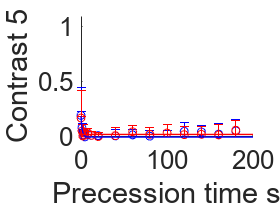

savefig(f_contrast_decay_3,[save_dir,'\Figure_c3_decay.fig'])

saveas(f_contrast_decay_5,[save_dir,'\Figure_c5_decay.png'])

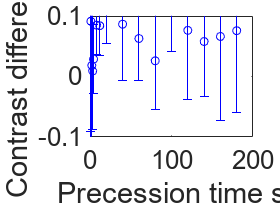

savefig(f_contrast_decay_5,[save_dir,'\Figure_c5_decay.fig'])

saveas(f_contrast_diff_decay_2,[save_dir,'\Figure_c_diff.png'])

savefig(f_contrast_diff_decay_2,[save_dir,'\Figure_c_diff.fig'])


## Plot frequency - two parts

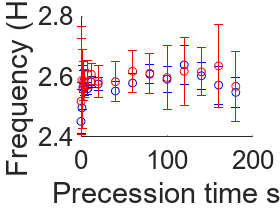

f_freq_2=figure;
hold all
h1=errorbar(precess_2_list',freq_1,freq_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',freq_2,freq_2_err,'o','Color','red');

% eqn='a*exp(-x^1/b^1)';
% startpoints=[0.5 1];
% lower=[0 0];
% upper=[1.1 2000000];
% 
% 
% fi_pop_coherent=fit(precess_2_list',contrast_1,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_1_err.^2);
% fi_pop_coherent_p1=fi_pop_coherent
% plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','blue');
% 
% fi_pop_coherent=fit(precess_2_list',contrast_2,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./contrast_2_err.^2);
% fi_pop_coherent_p2=fi_pop_coherent
% plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',1,'Color','red');
% 
ylabel('Frequency (Hz)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([2.4 2.8])
set(gca,'YScale','linear')

f_freq_diff_2=figure;

h1=errorbar(precess_2_list',freq_1-freq_2,sqrt(freq_1_err.^2+freq_2_err.^2),'o','Color','blue');

ylabel('Frequency difference (Hz)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.25 0.25])
set(gca,'YScale','linear')


saveas(f_freq_2,[save_dir,'\Figure_freq.png'])

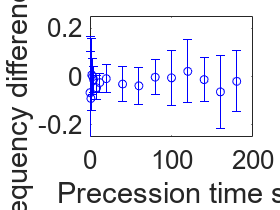

savefig(f_freq_2,[save_dir,'\Figure_freq.fig'])

saveas(f_freq_diff_2,[save_dir,'\Figure_freq_diff.png'])

savefig(f_freq_diff_2,[save_dir,'\Figure_freq_diff.fig'])


sum(freq_1./freq_1_err.^2+freq_2./freq_2_err.^2)./sum(1./freq_1_err.^2+1./freq_2_err.^2)

ans = 2.5790



xxxx=1:32;
freq_list=[freq_1',freq_2'];
freq_weight=[1./freq_1_err'.^2,1./freq_2_err'.^2];

g_I=0.27196;
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;

2.579/1/gyro_factor*2*pi*10^6

ans = 1.2441

0.004/1/gyro_factor*2*pi*10^6

ans = 0.0019

## Plot phase - two parts

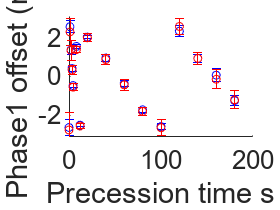

f_phase_1=figure;
hold all
h1=errorbar(precess_2_list',phase_1,phase_1_err,'o','Color','blue');
h2=errorbar(precess_2_list',phase_2,phase_2_err,'o','Color','red');

ylabel('Phase1 offset (rad)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-pi pi])
set(gca,'YScale','linear')

f_phase_3=figure;
hold all
h1=errorbar(precess_2_list',phase_3,phase_3_err,'o','Color','blue');
h2=errorbar(precess_2_list',phase_4,phase_4_err,'o','Color','red');

ylabel('Phase3 offset (rad)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-pi pi])
set(gca,'YScale','linear')

f_phase_5=figure;
hold all
h1=errorbar(precess_2_list',phase_5,phase_5_err,'o','Color','blue');
h2=errorbar(precess_2_list',phase_6,phase_6_err,'o','Color','red');

ylabel('Phase5 offset (rad)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-pi pi])
set(gca,'YScale','linear')

f_phase_diff_2=figure;

h1=errorbar(precess_2_list',phase_1-phase_2,sqrt(phase_1_err.^2+phase_2_err.^2),'o','Color','blue');

ylabel('Phase difference (rad)');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([-0.5 0.5])
set(gca,'YScale','linear')


saveas(f_phase_1,[save_dir,'\Figure_phase_1.png'])

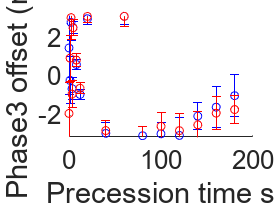

savefig(f_phase_1,[save_dir,'\Figure_phase_1.fig'])


saveas(f_phase_3,[save_dir,'\Figure_phase_3.png'])

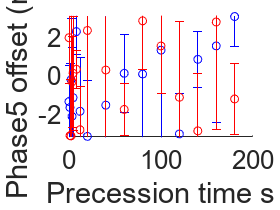

savefig(f_phase_3,[save_dir,'\Figure_phase_3.fig'])


saveas(f_phase_5,[save_dir,'\Figure_phase_5.png'])

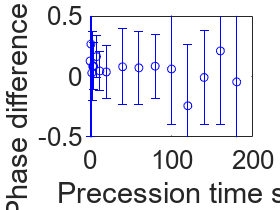

savefig(f_phase_5,[save_dir,'\Figure_phase_5.fig'])

saveas(f_phase_diff_2,[save_dir,'\Figure_freq_diff.png'])

savefig(f_phase_diff_2,[save_dir,'\Figure_freq_diff.fig'])


## population decay - average

p_average=(p_1'+p_2')./2;
p_average_err=sqrt(p_1_err'.^2+p_2_err'.^2)/2;

mean_3_1=reshape(mean_3,18,1,[]);
std_3_1=reshape(std_3,18,1,[]);

[mean_3_1_max,mean_3_1_max_id]=max(mean_3_1);
mean_3_1_max_std=std_3_1(mean_3_1_max_id);
population_timelist=precess_1_list(squeeze(mean_3_1_max_id))+sort([precess_2_list,precess_2_list+0.54]);
mean_3_max=squeeze(mean_3_1_max);
mean_3_max_std=squeeze(mean_3_1_max_std);
mean_3_max_weight=1./mean_3_max_std.^2;

figure
hold all
errorbar(population_timelist,mean_3_max,mean_3_max_std,'o')

mean_3_max=transpose(mean_3_max);
mean_3_max_std=transpose(mean_3_max_std);

mean_3_max(population_timelist>7)=[];
mean_3_max_std(population_timelist>7)=[];
population_timelist(population_timelist>7)=[];

population_timelist_2=precess_2_list;
p_average(population_timelist_2<7)=[];
p_average_err(population_timelist_2<7)=[];
population_timelist_2(population_timelist_2<7)=[];

population_timelist_all=[population_timelist,population_timelist_2];
p_average_all=[mean_3_max,p_average];
p_average_err_all=[mean_3_max_std,p_average_err];

errorbar(population_timelist_all,p_average_all,p_average_err_all,'o')


loss_factor=1/1.03;
p_average_all=p_average_all*loss_factor;
p_average_err_all=p_average_err_all*loss_factor;

eqn='a*exp(-x^1/b^1)+(1-a)';
startpoints=[0.5 1];
lower=[0 0 ];
upper=[1 20];

fi_pop_coherent=fit(population_timelist_all',p_average_all',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./p_average_err_all.^2);

fi_pop_coherent
f_pop_decay=figure
hold all
plot((0:1:200),fi_pop_coherent(0:1:200),'LineWidth',2,'Color',colors(5,:));
errorbar(population_timelist_all,p_average_all,p_average_err_all,'o')


savefig(f_pop_decay,[save_dir,'\p_decay.fig'])
saveas(f_pop_decay,[save_dir,'\p_decay.png'])


## Plot contrast decay - average

eqn='a*exp(-x/b)+c*exp(-x/d)';
startpoints=[1 1 1 1000];
lower=[0 0.1 0.5 500];
upper=[1 100 1 10000];

f_c_decay=figure

c_average=(contrast_1+contrast_2+contrast_3+contrast_4+contrast_5+contrast_6)./2;
c_average_err=sqrt(contrast_1_err.^2+contrast_2_err.^2+contrast_3_err.^2+contrast_4_err.^2+contrast_5_err.^2+contrast_6_err.^2)./2;

fi_c_cat=fit(precess_2_list',c_average,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./c_average_err.^2);
plot((0:1:200),fi_c_cat(0:1:200),'LineWidth',2,'Color',colors(5,:));
fi_c_cat

hold all

h1=errorbar(precess_2_list',c_average,c_average_err,'o');
ylabel('Contrast');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
ylim([0 1])
set(gca,'YScale','linear')

saveas(f_c_decay,[save_dir,'\c_decay.png'])
savefig(f_c_decay,[save_dir,'\c_decay.fig'])



## Sinusoidal fitting

eqn='a1*cos(2*pi*b1*x+c1)+a3*cos(2*pi*b1*3*x+c3)+a5*cos(2*pi*b1*5*x+c5)+d';
startpoints=[0.6 0.2 0.01 2.58 0 0 0 0];
lower=[0 0 0 2 -3.142*2 -3.142*4 -3.142*6 -1];
upper=[1 1 1 3  3.142*2  3.142*4  3.142*6  1];

chilist=[];

amp_1=zeros(1,length_2);
amp_3=zeros(1,length_2);
amp_5=zeros(1,length_2);

amp_err_1=zeros(1,length_2);
amp_err_3=zeros(1,length_2);
amp_err_5=zeros(1,length_2);

c_1=zeros(1,length_2);
c_3=zeros(1,length_2);
c_5=zeros(1,length_2);

c_err_1=zeros(1,length_2);
c_err_3=zeros(1,length_2);
c_err_5=zeros(1,length_2);


freq_1=zeros(1,length_2);
freq_err_1=zeros(1,length_2);

chilist=[];
chilist_reduced=[];

%h=figure;

for i = 1:size(mean_1,3)
    %for i=1:1
    fi=fit(precess_1_list',mean_1(:,:,i),eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',weight_1(:,:,i));
    fi_result{i}=fi;
    fi
    h=figure;
    hold on
    plot(precess_1_list_plot+precess_2_list(i),fi(precess_1_list_plot),'LineWidth',1.5,'Color',colors(5,:));
    hold on
    % plot(precess_1_list,mean_1(:,:,i)','.','MarkerSize',15,'Color',colors(8,:));

    I_se=errorbar(precess_1_list+precess_2_list(i),mean_1(:,:,i),std_1(:,:,i),'o');

    title([num2str(precess_2_list(i)),' s']);
    ylim([-1 1]);
    ylabel('S_z');
    xlabel('Precession time s');
    set(gca,'FontSize',16);
    xlim([x_lim_low+precess_2_list(i) x_lim_high+precess_2_list(i)])
    ylim([y_lim_low y_lim_high])

    I_se.Color=colors(9,:);
    I_se.MarkerSize=6;
    I_se.MarkerEdgeColor=colors(8,:);
    I_se.MarkerFaceColor=colors(5,:);

    amp_1(i)=fi.a1;
    amp_3(i)=fi.a3;
    amp_5(i)=fi.a5;

    c_1(i)=fi.c1;
    c_3(i)=fi.c3;
    c_5(i)=fi.c5;

    freq_1=fi.b1;

    temp = confint(fi);
    amp_err_1(i) = (temp(2)-temp(1))./4;
    amp_err_3(i) = (temp(4)-temp(3))./4;
    amp_err_5(i) = (temp(6)-temp(5))./4;

    c_err_1(i) = (temp(10)-temp(9))./4;
    c_err_3(i) = (temp(12)-temp(11))./4;
    c_err_5(i) = (temp(14)-temp(13))./4;

    freq_err_1=(temp(8)-temp(7))./4;

    chilist(i)=sum(((mean_1(:,:,i)-fi(precess_1_list))./std_1(:,:,i)).^2);
    chilist_reduced(i)=chilist(i)/(length(precess_1_list)-8);
    %     coefferr(i,:).*sqrt(chilist(i))
    saveas(h,[save_dir,'\Figure_',num2str(i),'.png'])
    savefig(h,[save_dir,'\Figure_',num2str(i),'.fig'])
end



## Plot differential & sensitivity

slope_max=zeros(1,size(mean_1,3));
slope_min=zeros(1,size(mean_1,3));

for i = 1:size(mean_1,3)
    [d1,d2] = differentiate(fi_result{i},precess_1_list_plot);
    slope_max(i)=max(d1);
    slope_min(i)=-min(d1);
    fi=fi_result{i};
    fi_parameter_bound=confint(fi);
    figure
    plot(precess_1_list_plot+precess_2_list(i),fi(precess_1_list_plot)*20,'LineWidth',1.5,'Color',colors(5,:));
    hold on
    plot(precess_1_list_plot+precess_2_list(i),d1,'LineWidth',1.5,'Color',colors(1,:));
    plot(precess_1_list_plot+precess_2_list(i),zeros(1,length(precess_1_list_plot+precess_2_list(i))))
    
end

precess_2_list_sensitivity=precess_2_list+mean(precess_1_list);

amp_all=amp_1+3*amp_3+5*amp_5;
amp_all_err=amp_err_1+3*amp_err_3+5*amp_err_5;

p_average=(p_1'+p_2')./2*loss_factor;
p_average_err=sqrt(p_1_err'.^2+p_2_err'.^2)/2*loss_factor;


sensitivity=1./precess_2_list_sensitivity./slope_max*1.2424e+03./((p_average').^0.5)';
sensitivity_error=(amp_all_err./amp_all).*sensitivity;
sensitivity_decay=figure;
%scatter(precess_2_list_sensitivity,sensitivity)
hold on
errorbar(precess_2_list_sensitivity(3:end),sensitivity(3:end),sensitivity_error(3:end),'o')
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
ylim([1e-2 100])
hold on

savefig(sensitivity_decay,[save_dir,'\SensitivityDecay.fig'])

hold on

g_I=0.27196;
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;

HL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5)/(gyro_factor/10^9))
SQL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(sqrt(5))/(gyro_factor/10^9))
mixed=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5/sqrt(16))/(gyro_factor/10^9))

eqn='a/x';
startpoints=[100];
lower=[1 ];
upper=[1000];

fi=fit(precess_2_list_sensitivity',sensitivity',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',1./sensitivity_error.^2,'Exclude',precess_2_list<2);
fi
errorbar(precess_2_list_sensitivity(3:end),sensitivity(3:end),sensitivity_error(3:end),'o')
hold on
plot(0.01:0.1:300,fi(0.01:0.1:300))
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
ylim([1e-2 100])



## Plot  sensitivity - fisher

g_I=0.27196;
nuclear_magneton=2*pi*7.6225932291*10^6;%Hz/T
gyro_factor=g_I*nuclear_magneton;


sensitivity_decay=figure;
%scatter(precess_2_list_sensitivity,sensitivity)
%hold on
%errorbar(precess_2_list_sensitivity,sensitivity,sensitivity_error,'o')
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([0.1 200])
%ylim([1e-5 10])
box on
errorbar(precess_2_list_sensitivity(3:end),sensitivity(3:end),sensitivity_error(3:end),'o','Color','red')
hold on

%scatter(precess_2_list_sensitivity,1./precess_2_list_sensitivity./sqrt(fisher)/(gyro_factor)*10^9)
set(gca,'XScale','log')
set(gca,'YScale','log')
xlim([1 300])
ylim([6e-2 1.05e2])

box on
HL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5)/(gyro_factor/10^9))
SQL=plot(0.001:0.1:500,1./(0.001:0.1:500)/(sqrt(5))/(gyro_factor/10^9))
mixed=plot(0.001:0.1:500,1./(0.001:0.1:500)/(5/sqrt(16))/(gyro_factor/10^9))
precess_2_list_sensitivity=precess_2_list+mean(precess_1_list);
fisher_t=fisher;
fisher_phi=fisher_t./(gyro_factor*1.2417e+03/10^9).^2;
fihser_B=fisher_phi.*(gyro_factor.*precess_2_list_sensitivity).^2;

scatter(precess_2_list_sensitivity,1./sqrt(fihser_B)*10^9,'Color','blue')

%savefig(sensitivity_decay,[save_dir,'\SensitivityDecay.fig'])

## Vacuum decay

% number decay
figure;
n_list=squeeze(mean_2(:,:,:));
n_std=squeeze(std_2(:,:,:));
[n_max,n_max_index]=max(n_list);
n_fit_weight=1./n_std.^2;

n_norm=n_list./n_max;
n_std_norm=n_std./n_max;

eqn='exp(-x/a)*b';
startpoints=[50 1];
lower=[20 0];
upper=[100 1];

fi=fit(precess_2_list(1:end)',n_norm(1:end),eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',n_fit_weight(1:end));
h=figure;
plot((0:1:200),fi(0:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

fi.a
temp = confint(fi);
(temp(2,:)-temp(1,:))/4

h3=errorbar(precess_2_list',n_norm,n_std_norm,'o');


ylabel('Atom number');
xlabel('Precession time s');
set(gca,'FontSize',20);
xlim([0 200])
h3.Color=colors(9,:);
h4.MarkerSize=6;
h3.MarkerEdgeColor=colors(8,:);
h3.MarkerFaceColor=colors(5,:);
set(gca,'YScale','log')
ylim([0.01 1])


## Save result

save([save_dir,'\average.mat'])